# Lista 2

**Zad. 1.**  Utwórz wektor `t` o 10 elementach 1,2,3...10. 

t = [1:10]

t =      1     2     3     4     5     6     7     8     9    10


Oblicz:


$$x = t\sin(t)$$


x = t.*sin(t)

x =     0.8415    1.8186    0.4234   -3.0272   -4.7946   -1.6765    4.5989    7.9149    3.7091   -5.4402



$$y = \frac{t-1}{t+1}$$


y = (t-1)./(t+1)

y =          0    0.3333    0.5000    0.6000    0.6667    0.7143    0.7500    0.7778    0.8000    0.8182



$$z = \frac{\sin(t^2)}{t^2}$$


z = (sin(t.^2))./(t.^2)

z =     0.8415   -0.1892    0.0458   -0.0180   -0.0053   -0.0275   -0.0195    0.0144   -0.0078   -0.0051


**Zad.2.** Równanie prostej ma postać $y=m\;x+c$, gdzie wartosći $m$ i $c$ są stałe. Oblicz współrzędne$y$ przy nachyleniu $m=0\ldotp 5$ oraz $c=-2$ dla następujących współrzędnych $x$:

`x = 0, 1.5, 3, 4, 5, 7, 9, 10.`

m = 0.5;
c = -2;
x = [0 1.5 3 4 5 6 9 10]

x =          0    1.5000    3.0000    4.0000    5.0000    6.0000    9.0000   10.0000


y = m.*x + c;

Proszę narysować otrzymane wyniki poleceniem: `plot(x,y)`

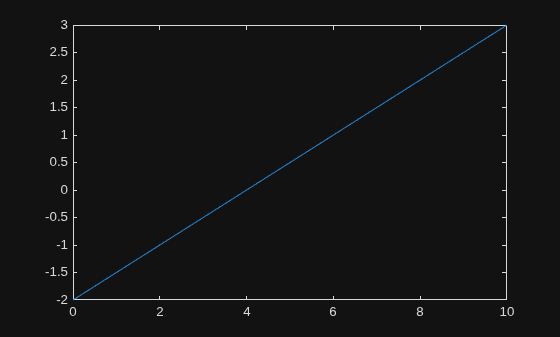

plot(x,y)

**Zad.3** Utwórz tablicę $A\left(10,10\right)$ zawierającą losowe liczby całkowite z przedziału $\left(0,50\right)$. 

A = round(rand(10).*50)

A =     41     8    33    35    22    14    38    42    18     4
    45    49     2     2    19    34    13    13    42     3
     6    48    42    14    38    33    25    41    29    27
    46    24    47     2    40     8    35    12    27    39
    32    40    34     5     9     6    45    46    46    47
     5     7    38    41    24    25    48    17    14     6
    14    21    37    35    22    48    27    10    38    28
    27    46    20    16    32    17     7    13    38    23
    48    40    33    48    35    29     7    31    19     1
    48    48     9     2    38    11    13    24    28    17


Napisz jedną instrukcję, która przekształca tablicę $A$ w następujący sposób:

- usuwa trzeci wiersz

A(3,:) = []

A =     41     8    33    35    22    14    38    42    18     4
    45    49     2     2    19    34    13    13    42     3
    46    24    47     2    40     8    35    12    27    39
    32    40    34     5     9     6    45    46    46    47
     5     7    38    41    24    25    48    17    14     6
    14    21    37    35    22    48    27    10    38    28
    27    46    20    16    32    17     7    13    38    23
    48    40    33    48    35    29     7    31    19     1
    48    48     9     2    38    11    13    24    28    17


- usuwa wiersze o parzstych numerach

A([2:2:end],:) = []

A =     41     8    33    35    22    14    38    42    18     4
    46    24    47     2    40     8    35    12    27    39
     5     7    38    41    24    25    48    17    14     6
    27    46    20    16    32    17     7    13    38    23
    48    48     9     2    38    11    13    24    28    17


- zastępuje trzeci wiersz wierszem postaci: 1, 2, 3, ...

A(3,:) = [1:10]'

A =     41     8    33    35    22    14    38    42    18     4
    46    24    47     2    40     8    35    12    27    39
     1     2     3     4     5     6     7     8     9    10
    27    46    20    16    32    17     7    13    38    23
    48    48     9     2    38    11    13    24    28    17


- dopisuje na dole tablicy wiersz samych jedynek

A(end,:) = ones(10,1)'

A =     41     8    33    35    22    14    38    42    18     4
    46    24    47     2    40     8    35    12    27    39
     1     2     3     4     5     6     7     8     9    10
    27    46    20    16    32    17     7    13    38    23
     1     1     1     1     1     1     1     1     1     1


- zamienia miejscami wiersz 1 i 4

A([1 3],:) = A([3 1],:)

A =      1     2     3     4     5     6     7     8     9    10
    46    24    47     2    40     8    35    12    27    39
    41     8    33    35    22    14    38    42    18     4
    27    46    20    16    32    17     7    13    38    23
     1     1     1     1     1     1     1     1     1     1


- zamienia miejscami kolumny drugą i ostatnią

A(:, [2 end]) = A(:, [end 2])

A =      1    10     3     4     5     6     7     8     9     2
    46    39    47     2    40     8    35    12    27    24
    41     4    33    35    22    14    38    42    18     8
    27    23    20    16    32    17     7    13    38    46
     1     1     1     1     1     1     1     1     1     1


**Zad. 4**. Utwórz tablicę $3\times 4$ z losowymi wartościami. Przekształć ją funkcją `reshape()` na wszystkie możliwe sposoby.

B = rand(3,4)

B =     0.2290    0.8258    0.0782    0.9619
    0.9133    0.5383    0.4427    0.0046
    0.1524    0.9961    0.1067    0.7749



reshape(B,[2 6])

ans =     0.2290    0.1524    0.5383    0.0782    0.1067    0.0046
    0.9133    0.8258    0.9961    0.4427    0.9619    0.7749


reshape(B,[4 3])

ans =     0.2290    0.5383    0.1067
    0.9133    0.9961    0.9619
    0.1524    0.0782    0.0046
    0.8258    0.4427    0.7749


reshape(B,[6 2])

ans =     0.2290    0.0782
    0.9133    0.4427
    0.1524    0.1067
    0.8258    0.9619
    0.5383    0.0046
    0.9961    0.7749


reshape(B,[12 1])

ans =     0.2290
    0.9133
    0.1524
    0.8258
    0.5383
    0.9961
    0.0782
    0.4427
    0.1067
    0.9619
    0.0046
    0.7749


**Zad. 5.** Utwórz tablicę $3\times 5$ z losowymi wartościami z zakresu -5 do 5 i przechowaj ją w jakiejś zmiennej. Utwórz inną zmienną, w której będą warstości bezwględne elementów pierwszej tablicy.

C = round(rand(3,5)*10-5)
D = abs(C)